## Lectura de datos

El imageDatastore permite manipular datos a gran escala, sin necesidad de cargar todas las imagenes a la vez.

Seria interesante 

dsModels = imageDatastore("Models\Meta\*.png");
dsTrain = imageDatastore(["Train1\Train1\", "Train2\Train2\"], "LabelSource","foldernames", "IncludeSubfolders",true);

%podemos mirar cuantos items de cada clase hay y la distribución:
%
eachLable = countEachLabel(dsTrain)

eachLable = 43×2 table
    Label    Count
    _____    _____

     0        210 
     1       2220 
     10      2010 
     11      1320 
     12      2100 
     13      2160 
     14       780 
     15       630 
     16       420 
     17      1110 
     18      1200 
     19       210 
     2       2250 
     20       360 
     21       330 
     22       390 


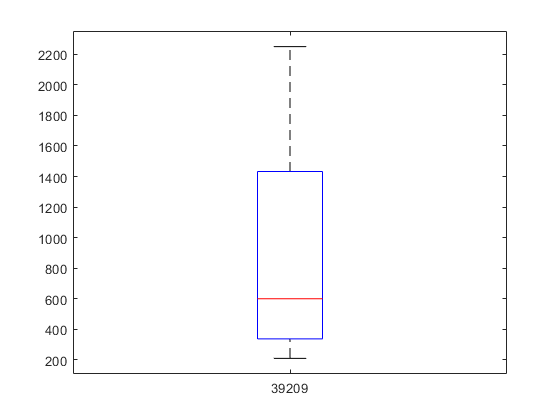

boxplot(eachLable.Count, nFiles);

%De la misma manera, aplicar un ordenado aleatorio tambien es comun en los
%preparativos para entrenar un modelo:
dsTrain = shuffle(dsTrain);

Es interesante que de cada clase hayan aproximadamente la misma cantidad de representantes, de otra manera el modelo puede estar desviado. (Esto mas adelante).

## Split Dataset

Ahora generaremos una particion en el datastore, un 80% sera para entrenar el modelo y el restante para test.

%numero de elementos
nFiles = numel(dsTrain.Files)

nFiles = 39209

[train,test] = splitEachLabel(dsTrain,0.8);
nTrain = numel(train.Files)

nTrain = 31367

nTest = numel(test.Files)

nTest = 7842

%[train,test] = splitEachLabel(dsTrain,0.8,'randomized');
% tmb se puede hacer con : subset

## Calcular Caracteristicas

Ahora hay que construir la tabla con los estadisticos que usaremos para entrenar el modelo.